# Define Parameters for Streaming Audio

Use the same parameters for the feature extraction pipeline and classification as trained network.

fs = 16000;
classificationRate = 20;
samplesPerCapture = fs/classificationRate;

segmentDuration = 1;
segmentSamples = round(segmentDuration*fs);

frameDuration = 0.025;
frameSamples = round(frameDuration*fs);

hopDuration = 0.010;
hopSamples = round(hopDuration*fs);

numSpectrumPerSpectrogram = floor((segmentSamples-frameSamples)/hopSamples) + 1;

# Define Feature Parameters for Streaming Audio

Create an [`audioFeatureExtractor`](https://kr.mathworks.com/help/audio/ref/audiofeatureextractor.html) object to extract Melspectrograms without window normalization. Calculate the number of elements in each spectrogram.

afe = audioFeatureExtractor( ...
    'SampleRate',fs, ...
    'FFTLength',512, ...
    'Window',hann(frameSamples,'periodic'), ...
    'OverlapLength',frameSamples - hopSamples, ...
    'melSpectrum',true);

numBands = 128;
setExtractorParams(afe,'melSpectrum','NumBands',numBands,'WindowNormalization',false);

numElementsPerSpectrogram = numSpectrumPerSpectrogram*numBands;

# Load Trained Model

Load the pretrained CNN and labels.

load('trainedNet.mat')
labels = trainedNet.Layers(end).Classes;
NumLabels = numel(labels);

# Define Audio Buffers

Define buffers and decision thresholds to post process network predictions.

probBuffer = single(zeros([NumLabels,classificationRate/2]));
YBuffer = single(NumLabels * ones(1, classificationRate/2)); 

countThreshold = ceil(classificationRate*0.2);
probThreshold = single(0.3);

# Create Streaming Audio Reader

Create an [`audioDeviceReader`](https://kr.mathworks.com/help/audio/ref/audiodevicereader-system-object.html) object to read audio from your device. Create a [`dsp.AsyncBuffer`](https://kr.mathworks.com/help/dsp/ref/dsp.asyncbuffer-system-object.html) object to buffer the audio into chunks.

adr = audioDeviceReader('Driver',"ALSA",'Device',"ALSAdefault", 'SampleRate', fs, 'SamplesPerFrame',samplesPerCapture, 'OutputDataType','single')

adr =   audioDeviceReader with properties:

             Device: 'ALSAdefault'
        NumChannels: 1
    SamplesPerFrame: 800
         SampleRate: 16000

  Show all properties


audioBuffer = dsp.AsyncBuffer(fs);

# Create Viewer for Streaming Audio

Create a [`dsp.MatrixViewer`](https://kr.mathworks.com/help/dsp/ref/dsp.matrixviewer-system-object.html) object and a [`timescope`](https://kr.mathworks.com/help/dsp/ref/timescope.html) object to display the results.

matrixViewer = dsp.MatrixViewer("ColorBarLabel","Power per band (dB/Band)",...
    "XLabel","Frames",...
    "YLabel","Mel Bands", ...
    "Position",[400 100 600 250], ...
    "ColorLimits",[-4 2.6445], ...
    "AxisOrigin","Lower left corner", ...
    "Name","Speech Command Recognition using Deep Learning");

timeScope = timescope("SampleRate",fs, ...
    "YLimits",[-1 1], ...
    "Position",[400 380 600 250], ...
    "Name","Speech Command Recognition Using Deep Learning", ...
    "TimeSpanSource","Property", ...
    "TimeSpan",1, ...
    "BufferLength",fs, ...
    "YLabel","Amplitude", ...
    "ShowGrid",true);

# Show Streaming Audio

Show the time scope and matrix viewer. Detect commands as long as both the time scope and matrix viewer are open or until the time limit is reached. To stop the live detection before the time limit is reached, close the time scope window or matrix viewer window.

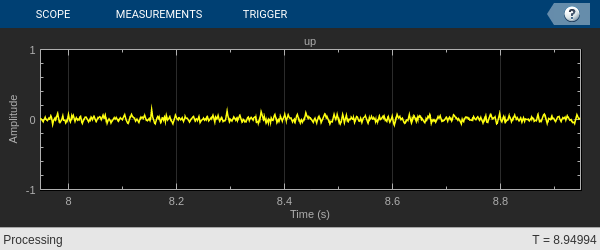

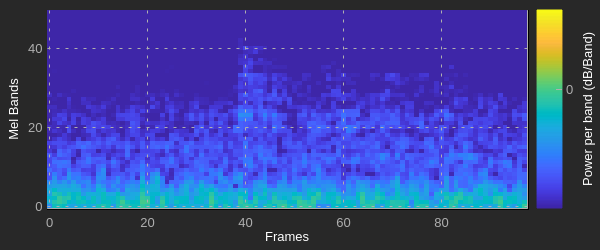

show(timeScope)
show(matrixViewer)

timeLimit = 100;

tic
while isVisible(timeScope) && isVisible(matrixViewer) && toc < timeLimit
    % Capture audio
    x = adr();
    write(audioBuffer,x);
    y = read(audioBuffer,fs,fs-samplesPerCapture);
    
    % Compute auditory features
    features = extract(afe,y);
    auditoryFeatures = log10(features + 1e-6);
    
    % Perform prediction
    probs = predict(trainedNet, auditoryFeatures);      
    [~, YPredicted] = max(probs);
    
    % Perform statistical post processing
    YBuffer = [YBuffer(2:end),YPredicted];
    probBuffer = [probBuffer(:,2:end),probs(:)];

    [YModeIdx, count] = mode(YBuffer);
    maxProb = max(probBuffer(YModeIdx,:));

    speechCommandIdx = YModeIdx;
    
    % Update plots
    matrixViewer(auditoryFeatures');
    timeScope(x);

    timeScope.Title = char(labels(speechCommandIdx));
    
    drawnow limitrate 
end  

Hide the scopes.

hide(matrixViewer)
hide(timeScope)

cfg =     Description: 'class EmbeddedCodeConfig: C code generation Embedded Coder configuration objects.'
    Name: 'EmbeddedCodeConfig'

-------------------------------- Report -------------------------------

        EnableAutoParallelizationReporting: true
                        EnableTraceability: true
                 GenerateCodeMetricsReport: false
             GenerateCodeReplacementReport: false
                            GenerateReport: false
          HighlightPotentialDataTypeIssues: false
                              LaunchReport: false
                         ReportInfoVarName: ''
                ReportPotentialDifferences: true
                                 Verbosity: 'Info'

------------------------------- Debugging -----------------------------

                             RuntimeChecks: false

---------------------------- Code Generation --------------------------

                        BuildConfiguration: 'Faster Runs'
                    CodeExecutionProf

### Updating Raspberry Pi I/O server...
### Connecting to board...
### Connected to 155.230.15.3...
### Creating server folder...
### Transferring source files...
### Building MATLAB I/O server...
### Launching MATLAB I/O server...


r =   raspi with properties:

         DeviceAddress: '155.230.15.3'                
                  Port: 18734                         
             BoardName: 'Raspberry Pi 4 Model B'      
         AvailableLEDs: {'led0'}                      
  AvailableDigitalPins: [4,5,6,12,13,14,15,16,17,18,19,20,21,22,23,24,25,26,27]
  AvailableSPIChannels: {'CE0','CE1'}                 
     AvailableI2CBuses: {'i2c-1'}                     
      AvailableWebcams: {}                            
           I2CBusSpeed: 100000                        

  Supported peripherals


applicationDirPaths = 1×8 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


targetDirPath = '/home/pi/remoteBuildDir/MATLAB_ws/R2021a/C/Users/Ahhyun_Yuh/Audio/Speech_Command_Recognition'